imagefiles = dir('VC/Final Project/DataFaces/images_faces/*.jpg');
for i = 1:length(imagefiles)
    currentimage = imagefiles(i).name;
    image = imread(currentimage);
    
    alto = height(image);
    ancho = width(image);
    x = floor(ancho/4);
    y = floor(alto/2.4);
    distance_h = floor(ancho/4 + ancho/2) - x;
    distance_w = floor(alto/1.9) - y;
    
    imwrite(imcrop(image, [x, y, distance_h, distance_w]), "eye_" + i + ".jpg");
end

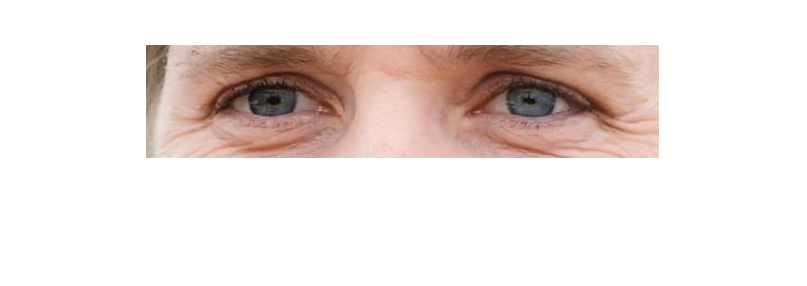

image = imread("DataFaces/images/000c3c3ebe3e1c1e.jpg");
    
alto = height(image);
ancho = width(image);
x = floor(ancho/4);
y = floor(alto/2.4);
distance_h = floor(ancho/4 + ancho/2) - x;
distance_w = floor(alto/1.9) - y;
imcrop(image, [x, y, distance_h, distance_w])